# **Analyzing Neural Time Series Data**

*Theory and Practice: Mike X Cohen*

*-------------------------------------------------------------------------------------------------------------------------------*

*Presented by: Armin Toghi*

*IDS Executive Member of Signal and Neuroimaging Department*

[armintoghi85@gmail.com](http://armintoghi85@gmail.com)

*--------------------------------------------------------------------------------------------------------------------------------*

### **The Purpose of This Book **

- Teach you the conceptual, mathematical, and implementational (via Matlab programming) bases of time-, time-frequency-, and synchronization-based analyses of magnetoencephalography (MEG), electroencephalography (EEG), and local field potential (LFP) recordings from humans and nonhuman animals.

- This book is about maximizing your freedom, at least when it comes to analyzing cognitive electrophysiology data.

- Once you have worked through the implementation and can see visually what the function does to input data, your eyelids raise, backs straighten, and you smile, because now you finally realize what the equation means

- This is the reason that this book comes with over 10,000 lines of Matlab code, and this is the reason why you will learn best from the book.

- The best way to go through this book is in front of a computer with Matlab installed and the code and sample data accompanying this book downloaded, so you can run the code and generate the figures that appear in the book.

- There are sample data and Matlab code for each session that I will send to you if necessary

### **Introduction to Matlab Programming**  

**Write Clean and Efficient Code**

- Use comment that you can understand later; shape, size, dimention (*Note: Chatgpt comments are not alwyase useful*)

- Section codes by their common purpose; *(Note: use Run Section when you first encounter a code)*

- Use sensible and interpretable variable names

- Run faster                                                                                                                                                                        (*Note 1; dont create a variable multiple times; save and load it for later calls*) (*Note 2; *evaluating an equation inside a loop when it could be evaluated outside the loop)

- Avoid working on multiple copies of the same analysis script. (Note: If you modify functions that come with Matlab toolbox such as eeglab or fieldtrip, it is a good idea to save the original function with a different file name. For example, you can save the file as “ filename.m.orig ” and then modify “ filename.m. ”)

- Initializing variables before populating with data (*Note: particularly for large matrices, helps avoid memory crashes*)

- Help!

- Plot the data before and after using a function

**Common Errors in IDS groups**

- Loading data, variable, or functions

- Dont look at dimentions

- Repeatedly send the error to Chatgpt without reading the error themselves

*-----------------------------------------------------------------------------------------------------------------------------*

**Basic Matlab codes:**

% Variables

a = 10;
b = 20;

% Run: highlight them here and hit F9
% a semicolon, the output is suppressed, and when there is no semicolon, 
% it outputs the results in the command window.

% You can also assign matrices to variables:
a_simple_matrix=[ 3 4 5; 1 2 3; 9 8 7 ];

% type this into the command to see how the semicolon was used to delineate
% separate lines.

var1{1} = [ 1 2 3 4 5 6 7 ];
var1{2} = 'hello world';
var1{3} = [ 1 3 6 7 4 3 5 6 7 87 76 43 4 5 6 767 ];
% Variables can be more sophisticated. Variables can be cells, which
% are like blocks that may contain different kinds of information.


% The function 'clear' removes all data from the matlab buffer
clear

% The function clc remove comman window
clc

% The most flexible type of variable is a structure. Structures contain fields that 
% are used for different kinds of data. For example:

ANTS.name = 'Armin'; % ANTS = Analyzing Neural Time Series
ANTS.position = 'Researcher';
ANTS.favorite_song = 'Bach; Partita Chaconne';
ANTS.the_worst_food_ever = 'Khoresht karafs';
ANTS.favorite_color = [ .8 .1 .8 ]; % RGB values

% or information about one field within one member:
ANTS.the_worst_food_ever

ans = 'Khoresht karafs'

% Functions

% functions are modular pieces of code stored in a separate file. Most
% functions can be opened and you can see/modify the code. Some functions
% are compiled and not viewable or editable.

% Functions may take inputs:
randperm(4) % randperm is a function that randomly permutes integers. 4 is the input. 

ans =      1     3     2     4



% or a vector:
mean([1 3 2 4 3 5 4 6])

ans = 3.5000


% IMPORTANT! Do not modify matlab functions unless you really know what
% you're doing! A better idea is to copy the function into a different file
% and use a different name.

% some functions can have multiple inputs: 
random_number_matrix = rand(4,6); % Here, we asked for a 4 x 6 matrix of random numbers


% some functions have multiple outputs:
max_value = max([1 2 3 9 8 7 6]);
% This also shows matrix indexing, which we'll get to soon. 

% IMPORTANT: You can use the output of one function as the input to another
% function. This is a powerful way to make your matlab programming fast and
% efficient. On the other hand, if you embed functions to an extreme you
% might unreadable code.
[max_value max_value_index] = max( randperm( round( rand(1)*10)));

% Indexing

% Indexing is a powerful tool in matlab to access particular parts of a
% variable. Indexing is very simple: Imagine you have 100 twinkies arranged
% in a 10 x 10 square: 
twinkies = rand(10,10);

% If you wanted to eat the twinkie in the 4th row, 8th column, you write:
the_twinkie_i_will_eat = twinkies(4,8);

%% The colon operator

% By default, the colon operator increments in integer units from the 
% first to the second number. Observe:
1:10

ans =      1     2     3     4     5     6     7     8     9    10


% You can also increment by a certain amount:
1:2:10

ans =      1     3     5     7     9


count2ten=1:.23956:10;

% the colon operator is also useful when indexing. Let's say you want to
% eat several twinkies:
twinkies_i_will_eat = twinkies(4:8,2:7);

% Question: How big should the variable twinkies_i_will_eat be? 
whos twin* % answer

  Name                      Size            Bytes  Class     Attributes

  twinkies                 10x10              800  double              
  twinkies_i_will_eat       5x6               240  double              




% To count backwards, you must specify that you want to skip with a negative number:
rookie_mistake     = 10:1;
how_the_pros_do_it = 10:-1:1;

%% determining the sizes of variables

% You can see variable sizes using whos, but there are also ways 
% to output matrix sizes into variables, which will be useful in many situations.

length(random_number_matrix)

ans = 6

% important! "length" returns the length of the longest dimension, regardless of how many dimensions there are!

% you can use size to find the sizes of all dimensions:
size(twinkies)

ans =     10    10


size(twinkies,1) % or only specific dimensions...

ans = 10


numel(twinkies) % numel stands for 'total number of elements'

ans = 100


% these functions also produce outputs:
twinkie_array_size = size(twinkies);
prod(twinkie_array_size) % prod returns the product of input numbers

ans = 100


% of course, these functions work on non-numeric variables, e.g.,
length(ANTS)

ans = 1

%% for-loops

% A for-loop is a way to iterate repeatedly:

for counting_variable = 1:10
    disp(counting_variable); % disp stands for display, which prints information in the command window
end

     1

     2

     3

     4

     5

     6

     7

     8

     9

    10




% another example:
for counting_variable = 1:2:10
    disp([ 'The ' num2str(counting_variable) 'th iteration value times 2 divided by 3 and added to 7 is ' num2str(counting_variable*2/3+7) '.' ])
end

The 1th iteration value times 2 divided by 3 and added to 7 is 7.6667.
The 3th iteration value times 2 divided by 3 and added to 7 is 9.
The 5th iteration value times 2 divided by 3 and added to 7 is 10.3333.
The 7th iteration value times 2 divided by 3 and added to 7 is 11.6667.
The 9th iteration value times 2 divided by 3 and added to 7 is 13.




% You can embed loops within loops
for i = 1:5
    for j = 3:7
        product_matrix(i,j) = i*j; % why there is a red underline the product_matrix?
    end
end

% Two important things to note here: (1) You can use the same numbers as
% indices AND as variables; (2) Unspecified elements in a matrix are
% automatically created and set to zero. 

number_rows    = 5; % having many spaces is allowed and facilitates code aesthetics
number_columns = 7;


% initialize matrix with zeros
product_matrix = zeros(number_rows,number_columns);

for i=1:number_rows
    for j=1:number_columns
        product_matrix(i,j)=i*j;
    end % end j-loop
end % end i-loop

% note the comments following end-statements. When you have multiple long
% loops, this kind of commenting will be helpful. Also note that when you 
% click on one of the "for" or "end" statements, its pair will be underlined. 

%% if-statements

% Exactly how it sounds
if 4>5
    disp('Something has gone awry in the universe')
end

if 4>5
    disp('Something is still very wrong')
else
    disp('Whew! Everything''s normal.') % note the two single-parenthesis marks inside the string
end

Whew! Everything's normal.



% the 'switch/case' statement is similar to 'if/else'
for counting_variable = 1:2:10
    switch counting_variable
        case 1 % compares 'counting_variable' to '1'
            disp([ 'The ' num2str(counting_variable) 'st iteration value times 2 divided by 3 and added to 7 is ' num2str(counting_variable*2/3+7) '.' ])
        case 2
            disp([ 'The ' num2str(counting_variable) 'nd iteration value times 2 divided by 3 and added to 7 is ' num2str(counting_variable*2/3+7) '.' ])
        case 3
            disp([ 'The ' num2str(counting_variable) 'rd iteration value times 2 divided by 3 and added to 7 is ' num2str(counting_variable*2/3+7) '.' ])
        otherwise
            disp([ 'The ' num2str(counting_variable) 'th iteration value times 2 divided by 3 and added to 7 is ' num2str(counting_variable*2/3+7) '.' ])
    end % end switch
end

The 1st iteration value times 2 divided by 3 and added to 7 is 7.6667.


The 3rd iteration value times 2 divided by 3 and added to 7 is 9.


The 5th iteration value times 2 divided by 3 and added to 7 is 10.3333.
The 7th iteration value times 2 divided by 3 and added to 7 is 11.6667.
The 9th iteration value times 2 divided by 3 and added to 7 is 13.


%% boolean (true/false)

% sometimes, it's useful to know if a statement is TRUE or FALSE. 
% You can use a double-equals sign:
% The answer is '1', which in this case means 'true'. The oppose of true (1) is false (0):

5==5

ans = logical
   1


5==4


ans = logical
   0


% You can assign these answers to variables:
fourIsFive = 4==5; % see below for disambiguating = and ==

whos fourIsFive % whos is a long form of WHO.  It lists all the variables in the current workspace,

  Name            Size            Bytes  Class      Attributes

  fourIsFive      1x1                 1  logical              



% note that 'fourIsFive' is type "logical", or boolean. 

% you can use the tilde "~" to negate a statement:
~(1==1) % false because the negation of 1==1 is false

ans = logical
   0


~(4>3)  % also false because the negation of 4>3 is false

ans = logical
   0


~(4<3)  % true because it is false (~) that 4 is greater than 3. Tricky!

ans = logical
   1


%% repmat

% repmat is short for "replicate matrix." It is a handy function that
% is often used in analyses. The problem that repmat solves is matrix
% operations with other matrices. First, consider that adding a scalar 
% (a single number) to a matrix is no problem. 

mat = rand(4);

mat+23

ans =    23.0377   23.0987   23.1366   23.4942
   23.8852   23.2619   23.7212   23.7791
   23.9133   23.3354   23.1068   23.7150
   23.7962   23.6797   23.6538   23.9037



% Now imagine that mat is EEG data with 4 electrodes and 10 time points:
mat = rand(4,10);

% now you want to subtract the mean over time:
meanOverTime = mean(mat,2); % second input to mean function is the dimension along which to compute the mean

mat = mat - meanOverTime;

% the previous line crashes because the matrices are of unequal size
whos mat meanOverTime

  Name              Size            Bytes  Class     Attributes

  mat               4x10              320  double              
  meanOverTime      4x1                32  double              




% repmat will help:
meanOverTimeRepmat = repmat(meanOverTime,1,size(mat,2));
whos mat meanOverTime*

  Name                    Size            Bytes  Class     Attributes

  mat                     4x10              320  double              
  meanOverTime            4x1                32  double              
  meanOverTimeRepmat      4x10              320  double              



% repmat takes 3 inputs: the matrix you want to replicate, the number of
% times to replicate it over rows, and the number of times to replicate it
% over columns (you can also input more dimensions). We want to replicate
% this matrix only over time points (the size of the second dimension of
% mat). Now the subtraction works:

matmean = mat - meanOverTimeRepmat;


% Other examples of repmat:
mat = [1 2 3; 10 20 30];

repmat(mat,1,1)

ans =      1     2     3
    10    20    30


repmat(mat,1,2)

ans =      1     2     3     1     2     3
    10    20    30    10    20    30


repmat(mat,2,1)

ans =      1     2     3
    10    20    30
     1     2     3
    10    20    30


%% bsxfun

% bsxfun is a useful function for fast and easy array and matrix manipulations.
% It was introduced to Matlab fairly recently, so older versions of Matlab
% do not have this utility. 

% for example, the following function will add 4 to a random matrix:
bsxfun(@plus,randn(10),4)

ans =     3.8528    4.1370    3.7461    4.1644    3.2159    5.4790    3.1777    3.6842    3.4300    2.5169
    5.0078    3.7081    2.5714    4.7477    2.1946    3.1392    3.9058    4.4286    2.9743    2.9797
    1.8763    4.3018    3.9791    3.7270    5.8586    4.7847    4.3362    2.9640    3.0913    3.5530
    3.4954    4.3999    3.4393    5.5763    3.3955    4.3086    3.0953    5.8779    3.7901    4.1097
    2.7294    3.0700    6.1778    3.5191    4.1034    3.7661    3.7117    4.9407    2.3011    5.1287
    3.6174    3.8232    5.1385    4.3275    4.5632    2.9430    4.3501    4.7873    4.6076    3.7100
    4.6487    1.8679    1.5031    4.6647    4.1136    3.7159    2.1641    3.1241    3.8822    5.2616
    4.8257    5.1454    4.4413    4.0852    3.0953    3.9133    5.0360    4.3199    4.6992    4.4754
    2.9851    3.3709    2.6019    4.8810    3.5323    2.5306    6.4245    3.4417    4.2696    5.1741
    3.5289    2.7962    3.7449    4.3232    3.8751    4.1922    4.9594    3.6886    4

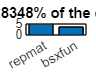


% this might not seem any better than "randn(10)+4" and for this small
% case, it isn't. bsxfun is more useful because it performs
% singleton-expansion, which means you may be able to avoid using repmat.
% For example, imagine a dataset with 100 channels and 100,000 time points: 
a  = rand(100,100000);

% To subtract the mean of the entire time series: 
am = a - repmat(mean(a,2),1,size(a,2));

% Notice that the repmat is necessary:
am = a - mean(a,2);

% The previous line crashes because the sizes of a and its mean are not the
% same. However, bsxfun expands this automatically
am = bsxfun(@minus,a,mean(a,2));

% let's do a timing test...
tic
for i=1:100
    am = a - repmat(mean(a,2),1,size(a,2));
end
t(1)=toc;

tic
for i=1:100
    am = bsxfun(@minus,a,mean(a,2));
end
t(2)=toc;

figure
bar(t)
set(gca,'xtick',1:2,'xticklabel',{'repmat';'bsxfun'},'xlim',[.5 2.5])
title([ 'bsxfun took ' num2str(100*t(2)/t(1)) '% of the computation time.' ])

% you'll learn more about the above lines in part B of this code


% Thus, bsxfun is a bit faster but also more convenient to use, and more elegant. 
% There are other similar functions to bsxfun, including arrayfun and cellfun. 
% In addition to speed, the *fun functions allow you to avoid using loops. 
% For example, let's say you want to know the length of items in a cell array. 

% create cell array whose elements have variable lengths
c = cell(1,40);
for i=1:length(c)
    c{i} = randn(1,round(rand*100));
end

% now you want to know how many elements are in each cell. 
% Normally you need a loop:
cell_lengths = zeros(size(c));
for i=1:length(c)
    cell_lengths(i) = numel(c{i});
end

% But cellfun is more efficient:
cell_lengths = cellfun(@length,c);

%% basic importing text data

% The most basic way to import data is to copy and paste. This is the best
% option for small amounts of numeric data that you'll need to put into matlab
% only once. (Hint: use square brackets.)

% The simplest way to read in text data is if all data in the next are
% numbers (no text). Open a text editor and make a small matrix (say, 3x4).
% Next, type: 
data = load('chapter04_datafile.txt');

% slightly more advanced:
[file_name,file_path]=uigetfile('*.txt'); % ui = user-interface
data = load([ file_path file_name ]);

% you can also read in data from excel files, but BE CAREFUL because this
% function can act in unexpected ways, e.g., by removing empty columns and
% rows without warning (this can be seen in comparing "numberdata" to "raw_data"). 
% Therefore, it might be best to use the "raw" data output. 
[numberdata,textdata,raw_data] = xlsread('chapter04_excel_data.xls');

%% initializing variables

num_rows = 10;
num_cols = 35;

% initialize with zeros (typical approach)
largematrix = zeros(num_rows,num_cols);

for rowi=1:num_rows
    for coli=1:num_cols
        % processing here...
    end % end row-loop
end % end column-loop

% note that you can increase the size of a matrix without initializing it
largematrix(num_rows+1,1) = 10;

% similarly, you can increase the dimensionality of a matrix
largematrix(1,round(num_cols/2),3) = 100;

% these last two options (adding elements and dimensions to an existing
% matrix) should be avoided whenever possible. They can create confusion and errors.

% you can also decrease matrix sizes/dimensions, ether by re-assignment:
largematrix = largematrix(:,:,1);

% or by setting parts of the matrix to be empty:
size(largematrix)
largematrix(:,end-4:end) = []; % this removes the last 5 columns
size(largematrix)

% Again, changing matrix sizes and dimensions should be avoided when
% possible, and done carefully when necessary.

%% basic saving data
x = rand(10,20);
% save as a .mat file (only matlab can read these files):
save('my_matlab_variables.mat','x'); 


### Exercise

1. Create a 4 × 8 matrix of randomly generated numbers.

2. Loop through all rows and columns, and test whether each element is greater than 0.5.

3. Report the results of the test along with the value of the matrix element and its row-column position. For example, your Matlab script should print : The 3rd row and 8th column has a value of 0.42345 and is not bigger than 0.5.

4. Make sure to add exceptions to print out 1st, 2nd, and 3rd, instead of 1th, 2th, and 3th.

5. Put this code into a separate function that you can call from the command line with two inputs, corresponding to the number of rows and the number of columns of the matrix.

6. From the function you wrote for exercise 5, generate a 32 × 3 number matrix in which the three numbers in each row correspond to the row, column, and result of the test (1 for bigger than 0.5; 0 for smaller than 0.5).

7. Write this 32 × 3 matrix to a text file that contains this matrix along with appropriate variable labels in the first row. Make sure this file is tab-delimited and readable by a spreadsheet software such as Microsoft Excel or Open Office Calc.

**Do it yourself; and at this stage dont use Chatgpt (I will definitly realize if you do)**

---------------------------------------------------------------------------------------------------------------------------------

Best wishes,

Armin Toghi

4 April 2025